# Simulating Deformation in Fluids

#### By: Arnaldo Rodriguez-Gonzalez

- This Live Script lets you observe the deformation of a fluid element over time as it moves along an arbitrary flow you define. 

- The graph on the left is constructed based on the scale of the trajectory of the fluid element and does not move over time. It displays the fluid element and its trajectory within the flow over time.

- The graph on the right is constructed based on the scale of the fluid element and follows the fluid element over time. It displays the fluid element and its deformation within the flow over time.

- Use the boxes to input the position and size of the fluid element, as well as the form of the flow. Then press the button to calculate the resulting deformation, and use the slider to see the deformation process occur over time.

- Make sure you run the entire Live Script before pressing any buttons to avoid spurious errors.

- This Live Script is intended to be an extrapolation of John Lumley's excellent video on deformation processes in fluids from 1963. See it [here](https://www.youtube.com/watch?v=Tmsn2qXbgXU).

- Am I the only one who thinks these kinds of videos are calming? I can't help but get migraines everytime I see some over-produced "explainer" video filled with so many jump-cuts that you'd think you're watching a Tony Scott film. Maybe I'm just getting old. 🤷

theta = linspace(0,2*pi,100);
xcenter = 0;
ycenter = 0.5;
radius = 0.05;
xline = linspace(xcenter-radius,xcenter+radius,101);
yline = linspace(ycenter-radius,ycenter+radius,101);
xcircle = radius*cos(theta) + xcenter;
ycircle = radius*sin(theta) + ycenter;
x0 = horzcat(xcircle,xline,xcenter+zeros(size(xline)));
y0 = horzcat(ycircle,ycenter+zeros(size(yline)),yline);
t = linspace(0,1,100);
vx=str2func(strcat('@(x,y) ',"x.^2 + y.^2"));
vy=str2func(strcat('@(x,y) ',"y + 3.*x"));
xcalc = zeros(length(t),length(x0));
ycalc = zeros(length(t),length(y0));
zcalc = zeros(length(theta),2);
for counter = 1:length(x0)
    [~,zcalc] = ode45(@(t,z) velint(t,z,vx,vy),t,[x0(counter) y0(counter)]);
    xcalc(:,counter) = zcalc(:,1);
    ycalc(:,counter) = zcalc(:,2);
end
lim = (11/10)*max(max(abs(xcalc),[],'all'),max(abs(ycalc),[],'all'));
[xg,yg] = meshgrid(linspace(-lim,lim,21));
null=0*xg;
 

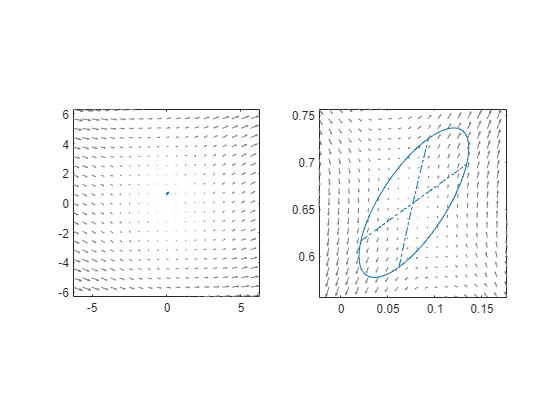

lim = (11/10)*max(max(abs(xcalc),[],'all'),max(abs(ycalc),[],'all'));
teval =24;
sminxlim = xcalc(teval,151)-2*radius;
smaxxlim = xcalc(teval,151)+2*radius;
sminylim = ycalc(teval,151)-2*radius;
smaxylim = ycalc(teval,151)+2*radius;
[x2g,y2g] = meshgrid(linspace(sminxlim,smaxxlim,20),linspace(sminylim,smaxylim,20));
null2=0*x2g;
subplot(1,2,1)
p1 = plot(xcalc(teval,1:length(theta)),ycalc(teval,1:length(theta)),xcalc(teval,length(theta)+1:length(theta)+length(xline)),ycalc(teval,length(theta)+1:length(theta)+length(xline)),'-.',xcalc(teval,(length(theta)+length(xline)+1):(length(theta)+2*length(xline))),ycalc(teval,(length(theta)+length(xline)+1):(length(theta)+2*length(xline))),'-.');
p1(1).Color = [0 0.4470 0.7410];
p1(2).Color = [0 0.4470 0.7410];
p1(3).Color = [0 0.4470 0.7410];
hold on
p2=quiver(xg,yg,null+vx(xg,yg),null+vy(xg,yg));
p2.Color = [0.5 0.5 0.5];
p3 = plot(xcalc(1:teval,151),ycalc(1:teval,151),'Color',[0 0.4470 0.7410]);
hold off
axis([-lim lim -lim lim])
axis square
subplot(1,2,2)
p4 =plot(xcalc(teval,1:length(theta)),ycalc(teval,1:length(theta)),xcalc(teval,length(theta)+1:length(theta)+length(xline)),ycalc(teval,length(theta)+1:length(theta)+length(xline)),'-.',xcalc(teval,(length(theta)+length(xline)+1):(length(theta)+2*length(xline))),ycalc(teval,(length(theta)+length(xline)+1):(length(theta)+2*length(xline))),'-.');
p4(1).Color = [0 0.4470 0.7410];
p4(2).Color = [0 0.4470 0.7410];
p4(3).Color = [0 0.4470 0.7410];
hold on
p4=quiver(x2g,y2g,null2+vx(x2g,y2g)-vx(xcalc(teval,151),ycalc(teval,151)),null2+vy(x2g,y2g)-vy(xcalc(teval,151),ycalc(teval,151)));
p4.Color = [0.5 0.5 0.5];
hold off
axis([sminxlim smaxxlim sminylim smaxylim])
axis square

## Activities

- Pick a particular flow and initial location of your choice, and see how the circle deforms over time. Make the circle smaller, and look at it again. Repeat until the *type* of shape the circle deforms into doesn't change. What type of shape does the circle deform into?

- Try a couple of other flows and/or initial locations, and repeat the procedure above. Based on what you find, how would you characterize the different ways that a small fluid element can change/deform?

- Consider the flow $\vec{u}=(x,-y)$; this is the type of flow you would get if you shot two identical jets of water from the top/bottom directly at each other. How does a fluid element centered at the origin deform in this kind of flow?

- Consider the flow $\vec{u}=(2y,0)$; this is the type of flow you would get if you slide a plate horizontally with fixed velocity over a motionless layer of fluid supported by a motionless plate. How does a fluid element centered at the origin deform in this kind of flow?

- The flow field $\vec{u}=(y,-x)$ corresponds to solid-body clockwise rotation around the origin, like what you get if you steadily spin a glass of water. How does a fluid element in this flow change/deform over time? Does it depend on the initial location of the fluid element? On its size?

- The flow field $\vec{u}=\left(\frac{y}{{x^2+y^2}},\frac{-x}{{x^2+y^2}}\right)$corresponds to clockwise motion in a circular orbit around the origin, whose speed is inversely proportional to the distance from the origin. This is commonly called an "irrotational vortex", and is ubiquitous in nature; it's what flow down a drain or in a tornado does. How does a small fluid element in this flow change/deform over time? Does it depend on the initial location of the fluid element? Based on what you find above after a couple of different initial locations, in what ways does the name "irrotational vortex" for this flow make or not make sense?

- In general, the deformation of a fluid element is connected to a force per unit area called "stress" acting on the surface of the fluid element. What do you think those forces per unit area/stresses look like on the surface of a fluid element located at $(0,0)$ in the flow $\vec{u}=(25-y^2,0)$?

function dzdt = velint(t,z,vx,vy)
dzdt = zeros(2,1);
dzdt(1) = vx(z(1),z(2));
dzdt(2) = vy(z(1),z(2));
end